# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
%Deci.Folder.Raw         = ['/Users/RobReinhart/Documents/Data/Behavioral'];              % Raw Data Folder Directory
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\AB2\' 'RawDataStim'];
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
% Behavioral is 1 then 5
% Model is 1 then 4 then 5

% 1 is Trial definiton
% 2 is Preprocessing
% 3 is Artifact rejection
% 4 is Analysis
% 5 is Plotting

Deci.PCom               = false;  
%Deci.Folder.Version     = ['/Users/RobReinhart/Documents/Data/Processed_displace'];        % Output Folder Directory
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\AB2\' 'ProcessedDataStim'];

## 1. Trial Definitions

% Trial definition infomaton                                                                 % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [21 23];
Deci.DT.Displace.Markers = {[31 32] [51 52]};
Deci.DT.Displace.Duration =2;
Deci.DT.Displace.Num = 1;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Markers   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.Bisect = true;

## 5. Plotting

BlockTypes = @ceil;
CollapseBlocks = true;
CollapseSubjects = true;
CollapseTrials = true;
WriteExcel =  true;

Plot_2std;

Deci.Run.Behavior = false; % for single and double
Deci.Run.Extra = true; % for model, double, triplet, 2std

## ** 6. Run**

ans = struct with fields:
        Extra: [1×1 struct]
    CondTitle: {'Opt AB Corr'  'Opt CD Cor r'  'Opt AB Inc'  'Opt CD Inc'  'Wst AB Corr'  'Wst CD Corr'  'Wst AB Inc'  'Wst CD Inc'}


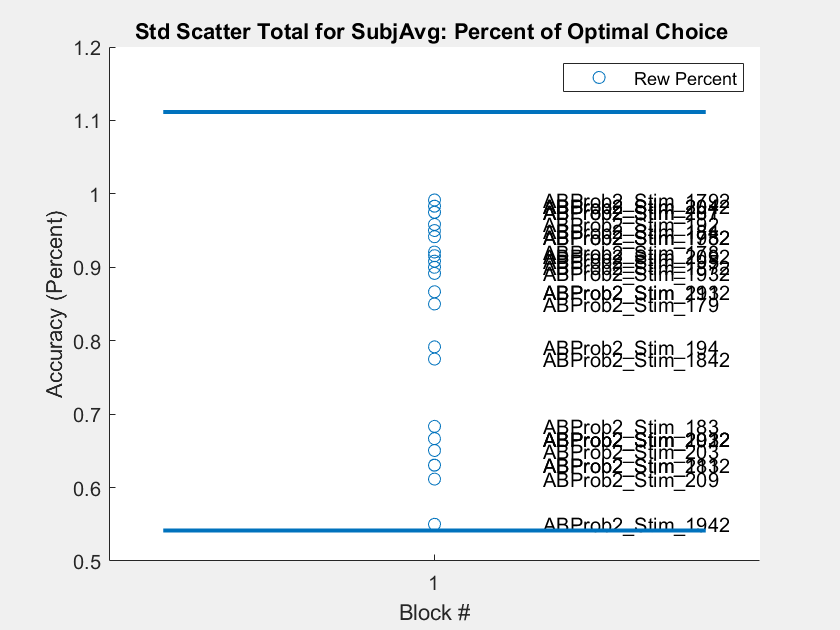

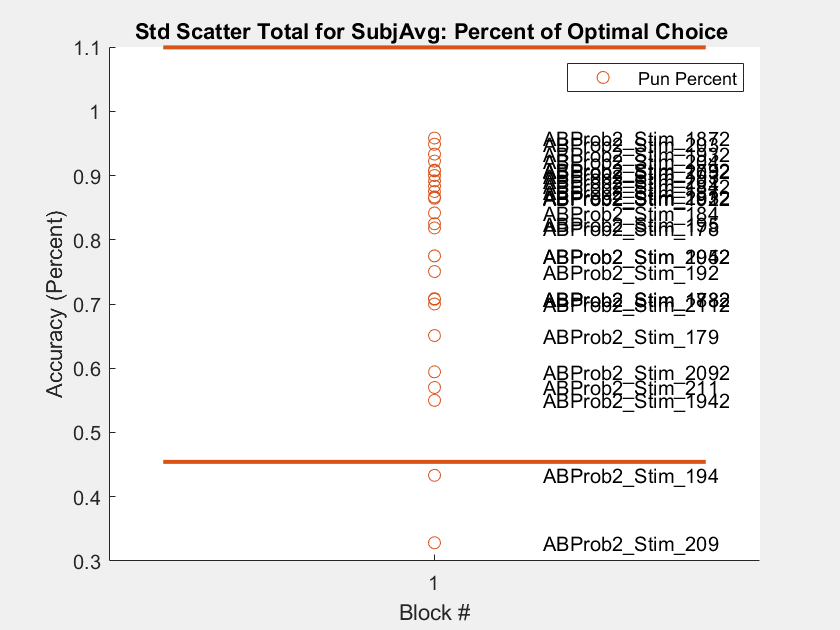

Deci_Backend(Deci);